# The behaviour of RC circuits 

RC circuits are one of the simplest circuits and it is important for all engineers to have an understanding of how these behave. As the basic model is first order, standard time and gain analysis is sufficient in the nominal case, but typical components may differ in reality leading to slightly different behaviours from that expected; this resource gives a simplified introduction and demonstration. An app is supplied to help provide a simpler interactive environment or exploring the impact of parameter changes.

You must have the symbolic toolbox installed for this file to work.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Introduction and modelling background

- Behaviour in the nominal case

- Behaviour with parasitic losses

- Use of the app

## 1. Introduction and modelling background

This app focused on the simple RC circuit. We investigate its nominal behaviour and also how behaviour changes with more realistic assumptions.

### 1.1 Nominal model

The RC circuit is shown in Figure 1.  A simple or nominal model for this is given as:


$$R\frac{\textrm{dq}}{\textrm{dt}}+\frac{q}{C}=v$$
 

where R is the resitance, C the capacitance and v the voltage. The state q is the charge across the capacitor.

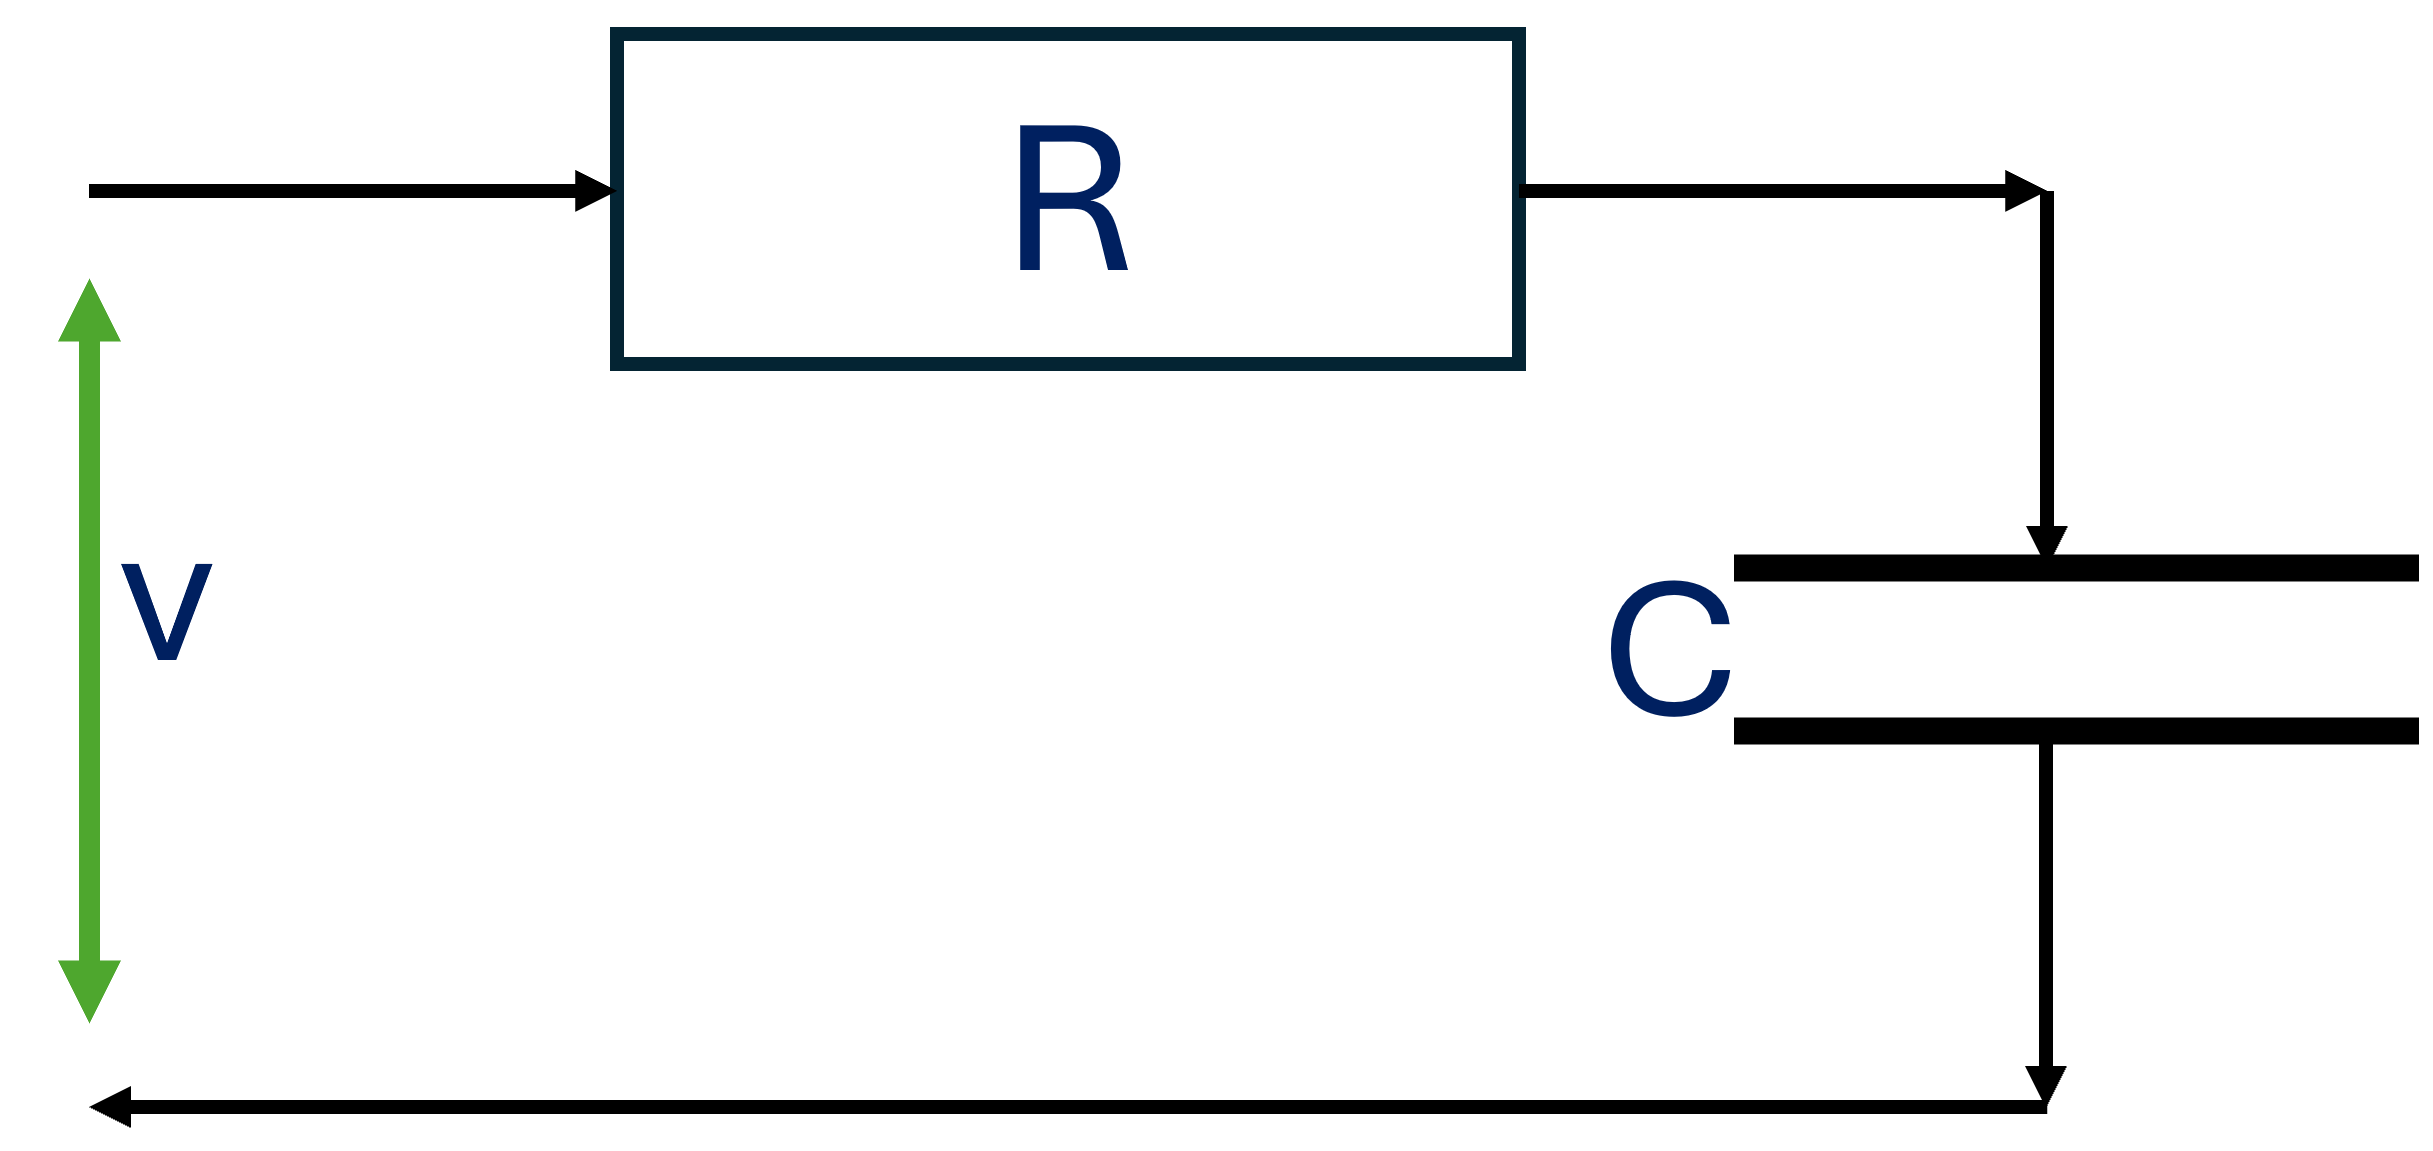

*Figure 1: Series RC circuit*

### 1.2 Model with parasitic losses

In practice the capacitor suffers some leakage across the plates which act in effect like a parallel resistor. This can be represented as in Figure 2 below. The model is now somewhat different and more complicated, as summarised in the equations below (alternative derivations exist but the end solution is the same).

${v=v}_1 +v_2$;   $v_1 =R\frac{\textrm{dq}}{\textrm{dt}};$


$$v_2 =R_2 \frac{dq_2 }{\textrm{dt}};\;v_2 =\frac{q_1 }{C};\;\;\;q=q_1 +q_2$$


Hence one can substitute:

 $R_2 \frac{dq_2 }{\textrm{dt}}=\frac{q_1 }{C}\;\;\Rightarrow \;q=R_2 C\frac{dq_2 }{\textrm{dt}}+q_2$;

Putting all these together gives:


$$v=R\frac{\textrm{dq}}{\textrm{dt}}+R_2 \frac{dq_2 }{\textrm{dt}}\;\Rightarrow \;\;v=R\frac{d}{\textrm{dt}}\left(R_2 C\frac{dq_2 }{\textrm{dt}}+q_2 \right)+R_2 \frac{dq_2 }{\textrm{dt}};$$



$$v=R\left(R_2 C\frac{d^2 q_2 }{\textrm{dt}}+\frac{dq_2 }{\textrm{dt}}\right)+R_2 \frac{dq_2 }{\textrm{dt}}$$
 

or using current:


$$v=RR_2 C\frac{di_2 }{\textrm{dt}}+\left({\;R}_2 +R\right)i_2$$
 

In time constant form this is:

$\left(\frac{1}{{\;R}_2 +R}\right)v=\left(\frac{RR_2 C}{{\;R}_2 +R}\right)\frac{di_2 }{\textrm{dt}}+i_2$;  $v_2 =R_2 i_2 ;$ $i=\frac{v-v_2 }{R}$

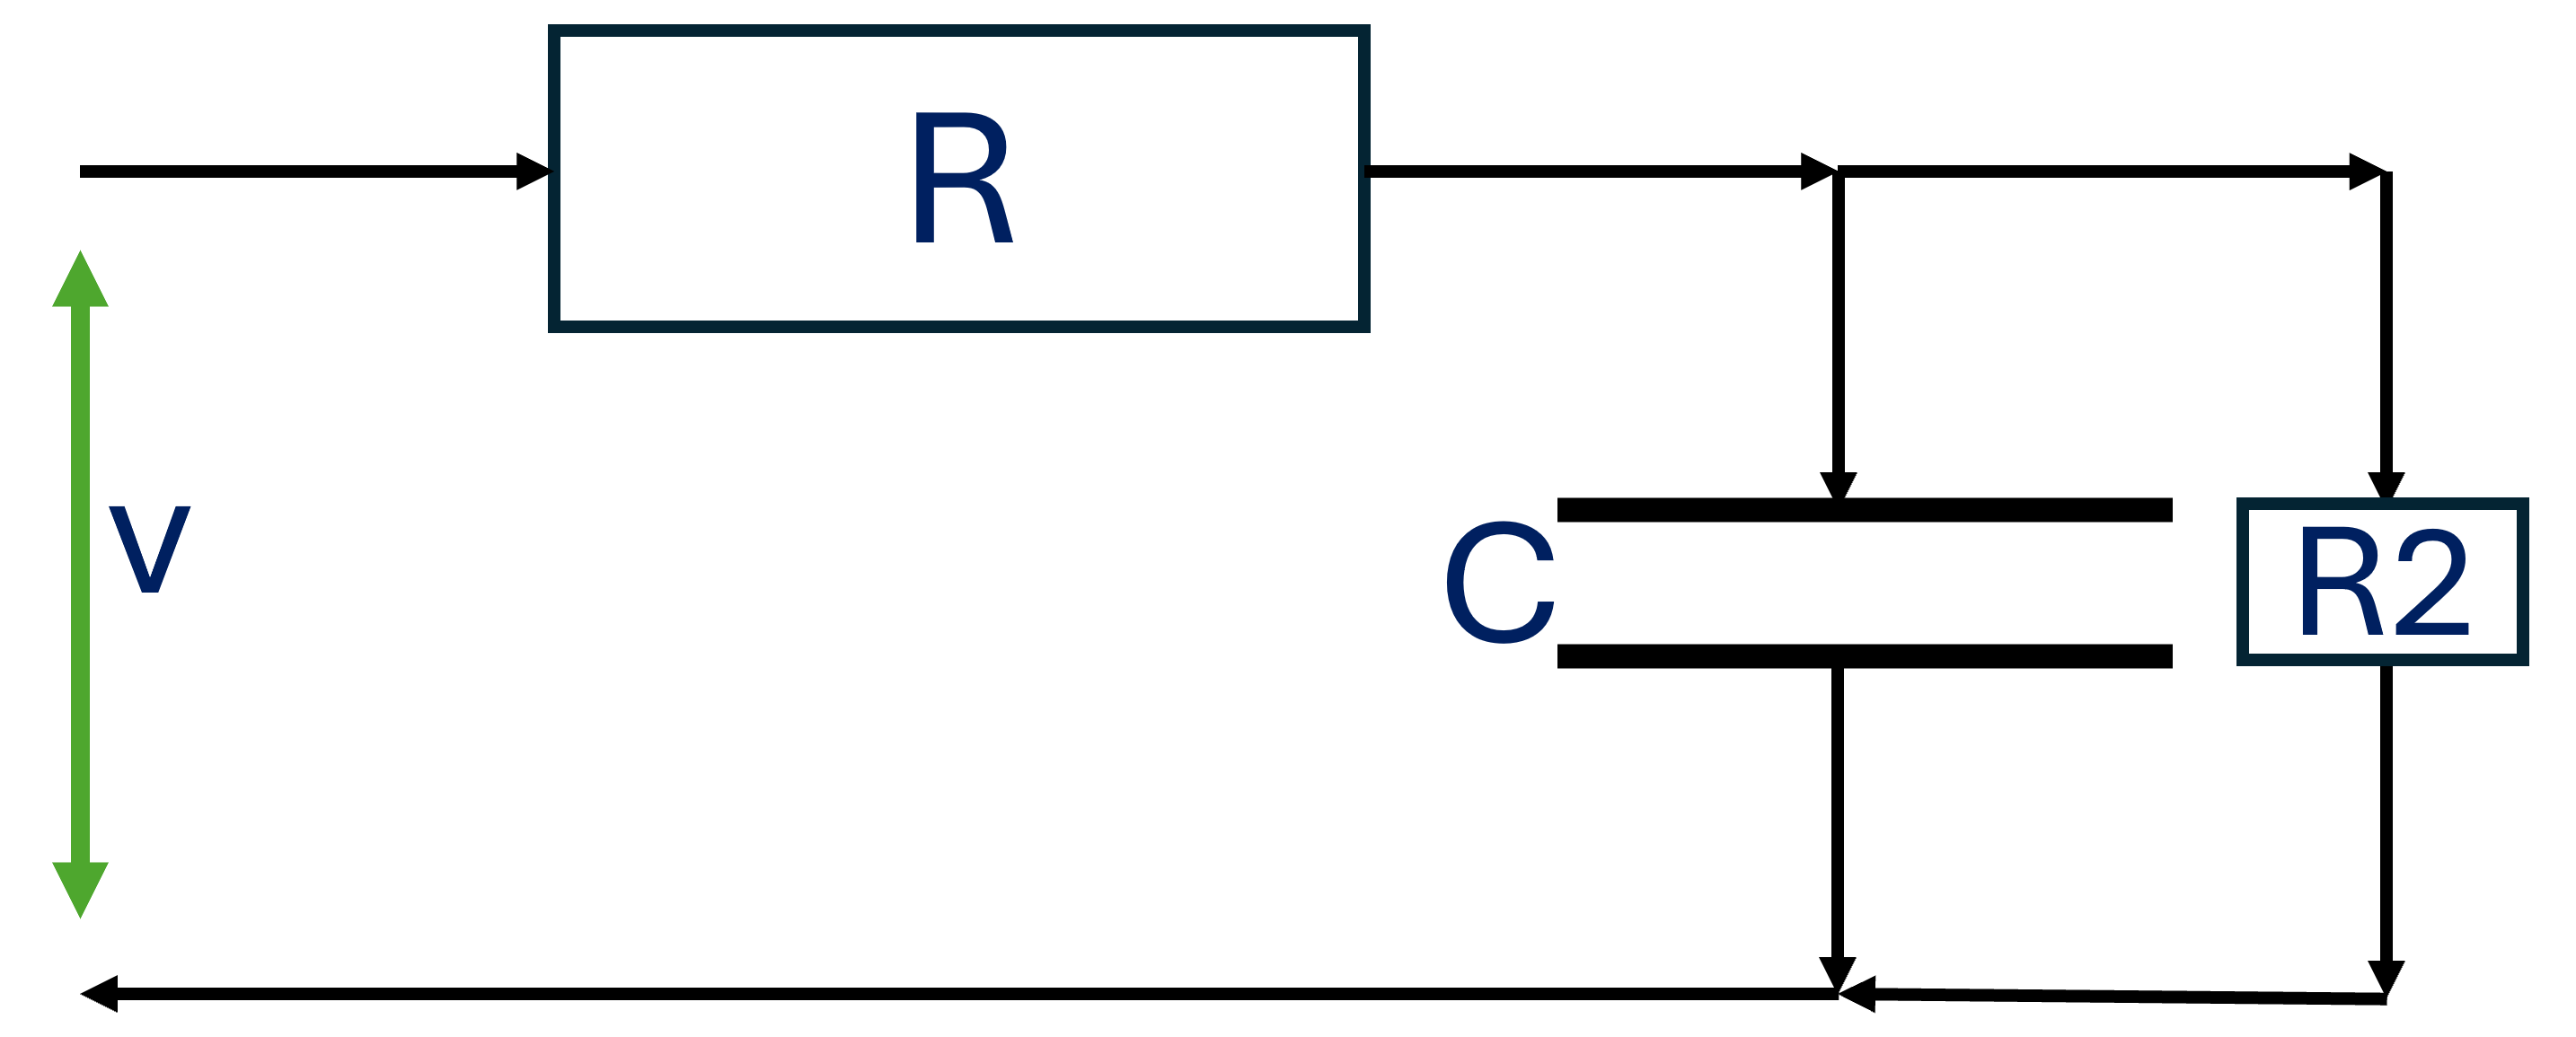

*Figure 2: Series RC circuit with parasitic losses in the capacitor*

## 2. Behaviour in the nominal case

The nominal case takes a standard time constant form.


$$R\;C\frac{\textrm{dq}}{\textrm{dt}}+q=C\;v$$
 

Discussion of time constant form is extensive elsewhere in the toolbox, so not discussed again here, for example files:   ***firstordermodels_responses_analysis_and_feedback,  carmodel_and_behaviour,  firstordermodel_behaviour,  firstordermodels_response_characterisation, HeatExchanger,  housetemperature_and_behaviour***.

We can investigate how behaviour changes with some simple code as follows. Users are encouraged to change the parameters and explore how behaviour changes.

% Define circuit parameters
R=1; C=0.02; v=5;
T=R*C; Gain =C;
syms q(t)
qt=dsolve(T*diff(q)+q==C*v,q(0)==0')

$$qt = \frac{1}{10}-\frac{{\mathrm{e}}^{-50\,t}}{10}$$

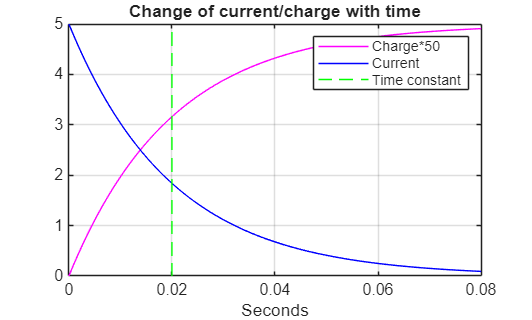



% Plotting
t=linspace(0,4*T,100);
q_values=subs(qt,t);
vt=q_values/C; % voltage on capacitor
it=(v-vt)/R;  % current flow
figure;clf reset; 
plot(t,q_values*50,'m',t,it,'b',[T,T],[0,max(it)],'g--');grid
legend('Charge*50','Current','Time constant')
title('Change of current/charge with time')
xlabel('Seconds')

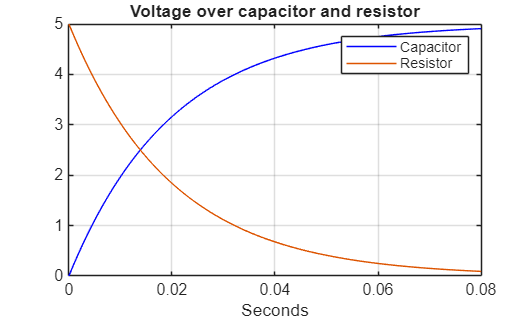


figure;clf reset; 
plot(t,vt,'b',t,v-vt);grid
title('Voltage over capacitor and resistor')
xlabel('Seconds')
legend('Capacitor','Resistor')

## 3. Behaviour with parasitic losses

It is interesting next to consider how behaviour changes when parasitic losses are introduced. For simplicity we will assume that the leakage resistance is R2, which should be considerably larger than R or it will dominate the loop behaviour and not be representative of a sensible example. We use the model from section 1, that is:

In time constant form this is:

$\left(\frac{1}{{\;R}_2 +R}\right)v=\left(\frac{RR_2 C}{{\;R}_2 +R}\right)\frac{di_2 }{\textrm{dt}}+i_2$;  $v_2 =R_2 i_2 ;$ $i=\frac{v-v_2 }{R}$

The simulations below shown how the current no longer drops to zero and there is a clear, albeit small, difference between the system with and without leakage (nominal).

**ACTIVITY**: Try changing the parameter values in section 2 and re-running the whole file to see the impact. This section assumes the core values have already been defined as in section 2.

disp('Section 3 is below here')

Section 3 is below here


% Define circuit parameters
R2=20*R; 
T2=R*R2*C/(R+R2);  Gain2=1/(R+R2);
syms i2(t)
i2t=dsolve(T2*diff(i2)+i2==Gain2*v,i2(0)==0')

$$i2t = \frac{5}{21}-\frac{5\,{\mathrm{e}}^{-\frac{105\,t}{2}}}{21}$$

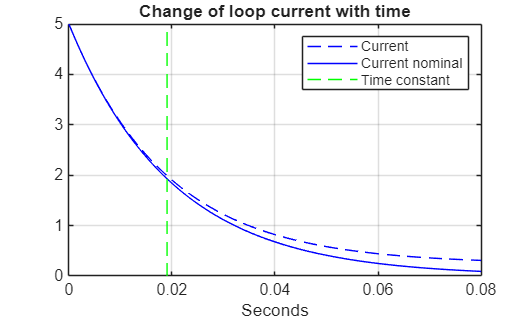

t=linspace(0,4*T,100);
i2_values=subs(i2t,t);
v2t=i2_values*R2; % voltage on capacitor
i_values=(v-v2t)/R;

% Plotting
figure;clf reset; 
plot(t,i_values,'b--',t,it,'b',[T2,T2],[0,max(i_values)],'g--');grid
legend('Current','Current nominal','Time constant')
title('Change of loop current with time')
xlabel('Seconds')

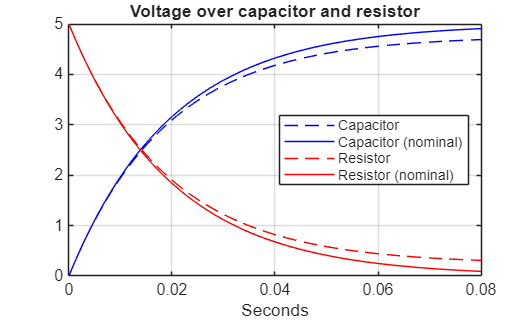


figure;clf reset; 
plot(t,v2t,'b--',t,vt,'b',t,v-v2t,'r--',t,v-vt,'r');grid
title('Voltage over capacitor and resistor')
xlabel('Seconds')
legend('Capacitor (leakage)','Capacitor (nominal)','Resistor (leakage)','Resistor (nominal)','Location','east')

## 4. Use of the app

An app interface has been produced to help visualise the differences for a small range of parameter values. The user selects the slider values required and then presses the simulate button. The animation shows how the current, voltage and charge vary over time.

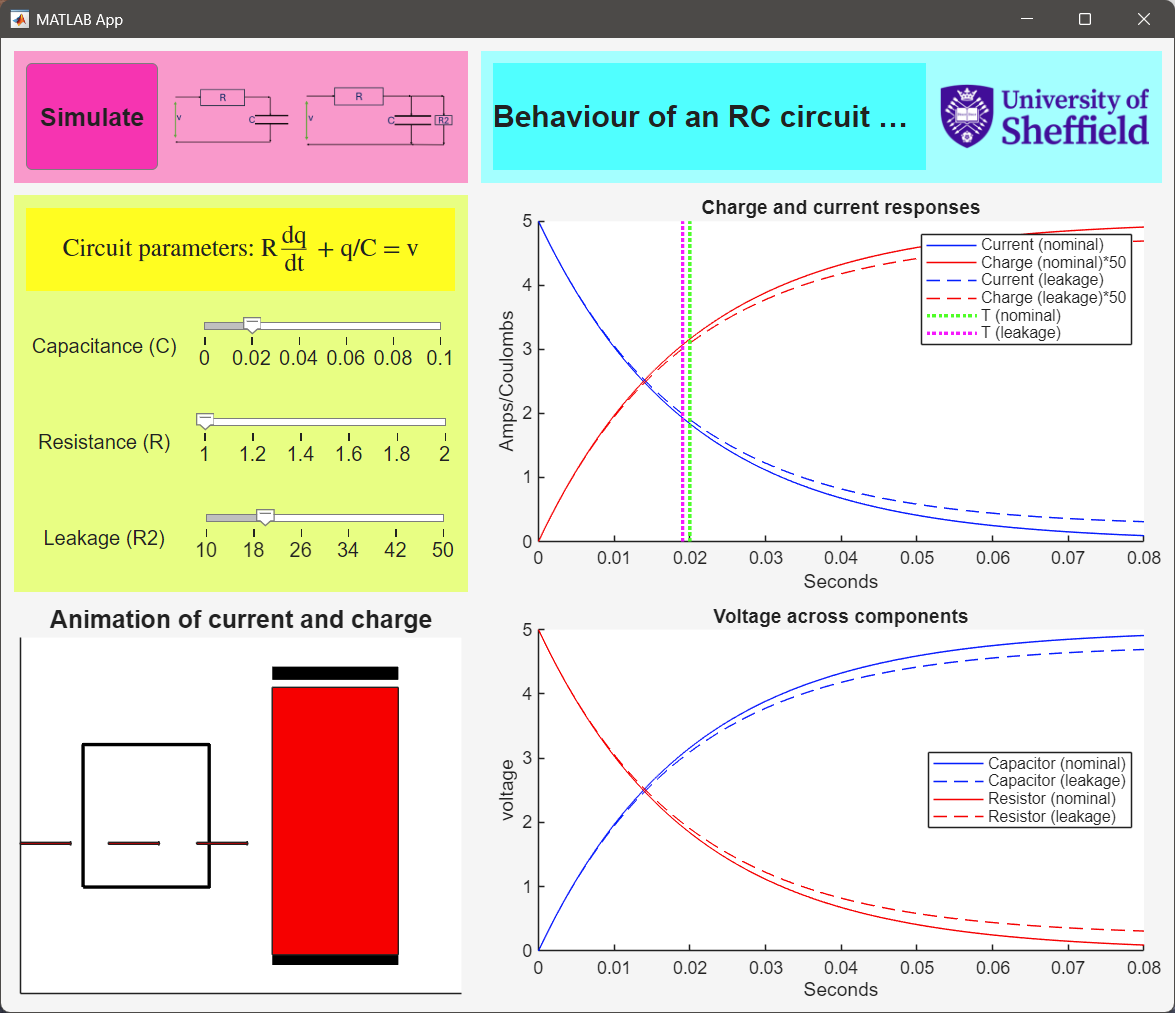

*Figure 3: Illustration of the app interface*